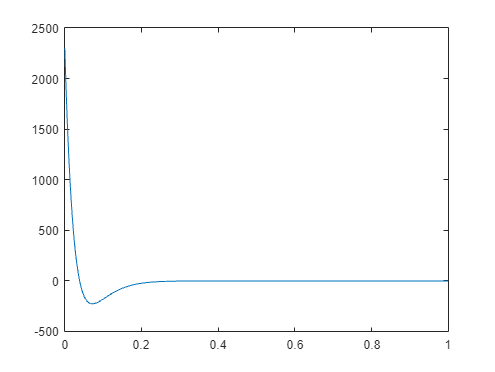

% Problem 1
clear all; clc; close all;

[t,y] = ode45(@(t,y) hill_muscle_model_ODE(t,y), 0:0.001:1, 0);
A = 48144 * exp(-t/0.0326) - 45845 * exp(-t/0.034);
A = A';

plot(t,A')

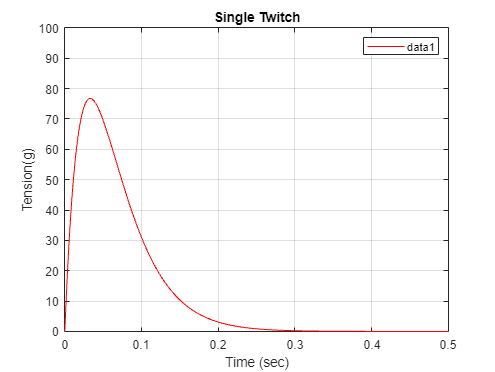


plot(t,y,'r')
title('Single Twitch')
xlabel('Time (sec)')
ylabel("Tension(g)")
legend("show")
xlim([0 0.5])
ylim([0 100])
grid on

# 1 th

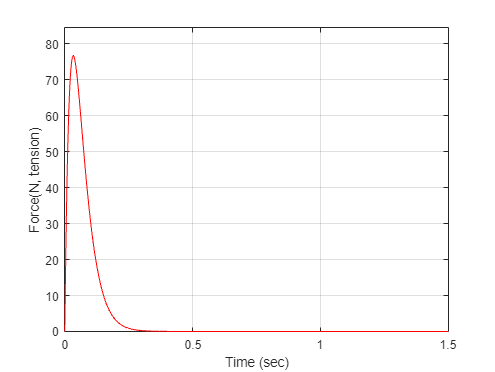

# 3 th

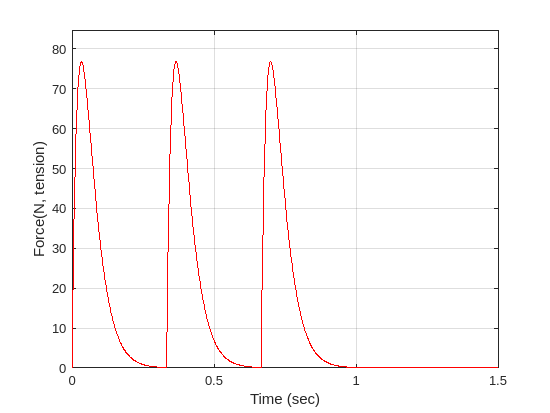

# 5 th

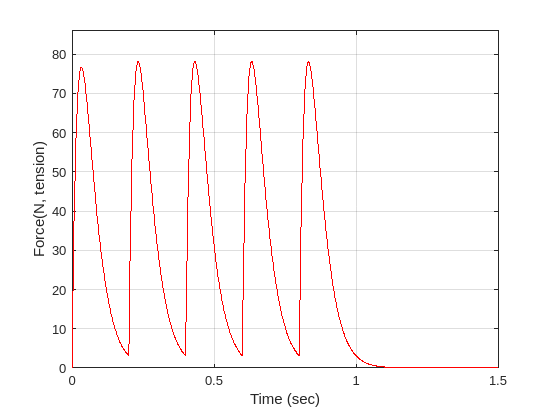

# 10 th

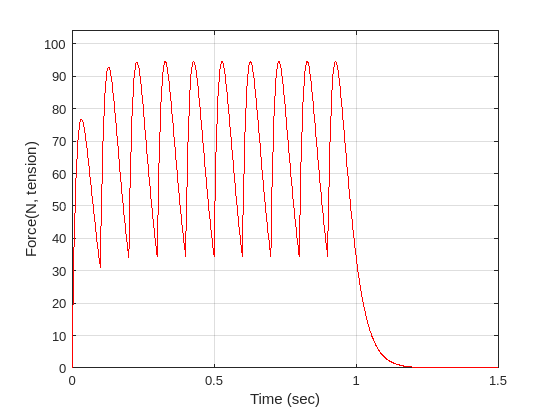

# 20 th

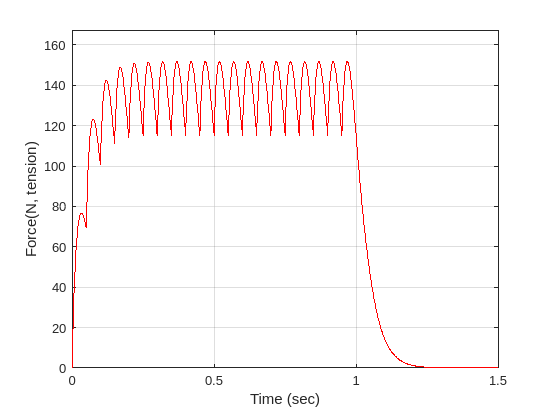

# 30 th

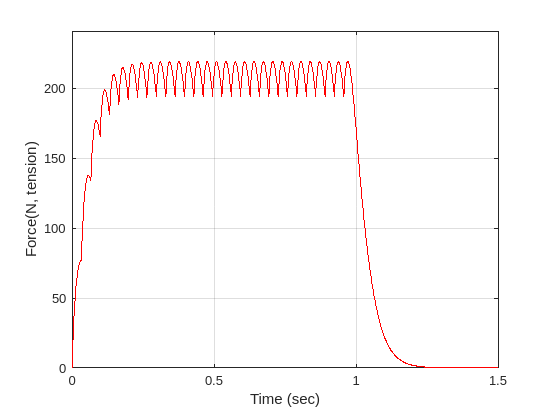

# 40 th

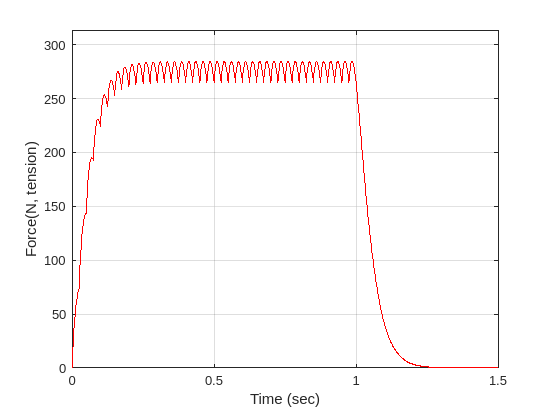


% parameters
max_freq = 40;      % Hz
T = 1000/max_freq;  % ms
x_n = 0:0.001:3;
input = y';

for i=1:1:max_freq
    new_total = zeros(1, 3001);
    r = round(1000/i);
    for j=0:i-1
        new_total(1+j*r : 1001+j*r) = new_total(1+j*r : 1001+j*r) + input(1:end);
    end

    if i==1
        fprintf("# %d th", i)
        figure(i)
        plot(x_n, new_total(1:3001), 'r')
        xlabel('Time (sec)')
        ylabel("Force(N, tension)")
        xlim([0 1.5])
        ylim([0 max(new_total)*1.1])
    end
    if i==3
        fprintf("# %d th", i)
        figure(i)
        plot(x_n, new_total(1:3001), 'r')
        xlabel('Time (sec)')
        ylabel("Force(N, tension)")
        xlim([0 1.5])
        ylim([0 max(new_total)*1.1])
    end
    if i==5
        fprintf("# %d th", i)
        figure(i)
        plot(x_n, new_total(1:3001), 'r')
        xlabel('Time (sec)')
        ylabel("Force(N, tension)")
        xlim([0 1.5])
        ylim([0 max(new_total)*1.1])
    end

    if mod(i,10)==0
        fprintf("# %d th", i)
        figure(i)
        plot(x_n, new_total(1:3001), 'r')
        xlabel('Time (sec)')
        ylabel("Force(N, tension)")
        xlim([0 1.5])
        ylim([0 max(new_total)*1.1])
    end
    grid on
end

function dydt = hill_muscle_model_ODE(t,y)

Kse=136; Kpe=75; b=50;
A = 48144 * exp(-t/0.0326) - 45845 * exp(-t/0.034);
delta_x=0;
dydt = (Kse/b) * ( Kpe * delta_x + b* delta_x - (1+Kpe/Kse)*y + A );
end
